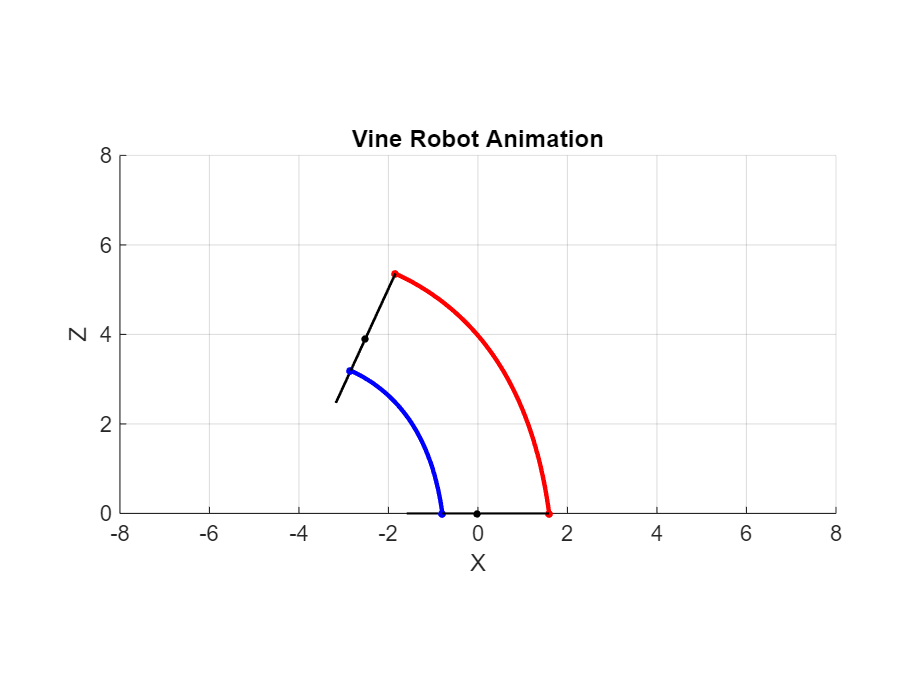

clear, close all


%Inputs
n = 2;
r = 2*5/pi/2; %in

L_init = 4;
L_40 = .017*40*L_init+L_init;
%Initial state 19.8 12.3 12.3
q_set = [L_40 ;L_init; L_init; 0.01; 0.01; 0.01]'; %Test lengths

%q_set = [4 ;6; 5; 0.01; 0.01; 0.01]'; %Test lengths
%2000x3n







animate_from_q_matrix(q_set,r ,.1)

view([0 -1 0])

%Lets try a better optimization function :)
function [deltaL,act_pose] = find_deltaL_new(q,des_pose,gamma,Kp,r,n)
    %J = calc_J(n,r,q);
    J = numerical_jacobian(q,r,n); %Numerical calculation, works somehow
    tip_T = find_tip(q,r,n);
    tip_T = real(tip_T);
    %Convert to an actual pose
    tip_pos = tip_T(1:3,4); %Tip position
    
    
    %tip_eul = rotm2eul(real(tip_T(1:3,1:3)))';  % returns [yaw, pitch, roll]
    %act_pose = [tip_pos;tip_eul];
    
    R_des = eul2rotm(des_pose(4:6)', 'ZYX');  % Assuming ZYX Euler input
    R_act = tip_T(1:3, 1:3);
    % Rotation error matrix
    R_err = R_des * R_act';  % NOTE: Not R_act * R_des'
    % Convert rotation error to rotation vector (axis * angle)
    % I don't really undersatand this part but its mroe stable than using
    % Euler angles
    axang = rotm2axang(real(R_err));  % [axis(1:3), angle]
    e_rot = axang(1:3)' * axang(4);  % rotation vector (3x1)

    % Full 6D error: [position_error; rotation_vector]
    pos_err = des_pose(1:3) - tip_pos;
    
    
    %TEST
    error = [pos_err; e_rot];
    % Output actual pose for logging
    act_eul = rotm2eul(real(R_act), 'ZYX')';
    act_pose = [tip_pos; act_eul];
    act_pose = real(act_pose);
    %deltaL = (J'*J+gamma*eye(3*n))\(J'*(Kp*error));
    H = J'*J + gamma*eye(3*n);
    f = -J' * (Kp * error);

    lb = 4-q;
    ub = 8-q;
    % Use quadprog to solve the QP
    options = optimoptions('quadprog','Display','off');
    deltaL = quadprog(H, f, [], [], [], [], lb, ub, [], options);
end



%Lets tryout LQI control :)
function [next_state, u_out, updated_integral] = LQI_control(Q, R, m, b, k, u_max, q_act, vel_act, q_ref, tstep, fullsim, integral_in)
    n = length(q_act);
    tspan = 10;

    if fullsim
        t_mat = 0:tstep:tspan;
    else
        t_mat = 0:tstep/2:tstep;
    end

    % Preallocate
    u_out = zeros(n, 1);
    next_state = zeros(2, n);
    updated_integral = zeros(n, 1);  % Output for integral term

    % System matrices
    A = [0 1;
        -k/m -b/m];
    B = [0;
         1/m];
    C = [1 0];

    % Augmented system
    sys = ss(A, B, C, 0);
    [K, ~, ~] = lqi(sys, Q, R);

    Kx = K(:, 1:2);  % Feedback
    Ki = K(:, 3);    % Integral

    for i = 1:n
        x_0 = [q_act(i);
               vel_act(i)];

        ref = q_ref(i);
        z_0 = integral_in(i);

        if fullsim
            x_aug_0 = [x_0; z_0];
            [t_LQI, x_LQI] = ode45(@(t, x) SMD_LQI(x, m, b, k, Kx, Ki, ref, u_max), t_mat, x_aug_0);
            final = x_LQI(end, :);
            next_state(:, i) = final(1:2);
            updated_integral(i) = final(3);
            u_out(i) = max(0, min(u_max, -Kx * final(1:2)' - Ki * final(3)));
        else
            % Update integral manually for one step
            err = ref - x_0(1);
            z_new = z_0 + err * tstep;
            u_in = -Kx * x_0 - Ki * z_new;
            u_in = max(0, min(u_max, u_in));
            [t_LQI, x_LQI] = ode45(@(t, x) SMD(x, m, b, k, u_in), t_mat, x_0);

            % Store final values
            final = x_LQI(end, :);
            next_state(1, i) = final(1);
            next_state(2, i) = final(2);
            updated_integral(i) = z_new;
            u_out(i) = u_in;
        end
    end

    if fullsim
        plot(t_LQI, x_LQI(:,1));
        xlabel('Time (s)');
        ylabel('Position');
        title('LQI Response');
    end
end

% LQI system with augmented state
function dx = SMD_LQI(x_aug, m, b, k, Kx, Ki, ref, u_max)
    x = x_aug(1:2);
    z = x_aug(3);
    u = -Kx * x - Ki * z;
    u = max(0, min(u_max, u));

    dx1 = x(2);
    dx2 = (1/m) * (-k * x(1) - b * x(2) + u);
    dz  = ref - x(1);
    dx = [dx1;
          dx2;
          dz];
end


%Function for animation
function animate_from_q_matrix(q_matrix, r_real, frame_delay)
    % Animate from a n_samples x 3*n matrix

    [num_samples, q_length] = size(q_matrix);

    if mod(q_length, 3) ~= 0
        error('Each row of q_matrix must be a multiple of 3 (i.e., 3*n).');
    end

    % array of q vectors
    q_sequences = cell(1, num_samples);
    for i = 1:num_samples
        q_sequences{i} = q_matrix(i, :);
    end

    % run animation
    animate_vine_robot(q_sequences, r_real, frame_delay);
end

function animate_vine_robot(q_sequences, r_real, frame_delay)
    % Animate multiple vine robot configurations given a vector of q values

    % defaults for radius and frame delay
    if nargin < 2 || isempty(r_real)
        r_real = 5*2/pi/2; 
    end
    if nargin < 3 || isempty(frame_delay)
        frame_delay = 0.5; 
    end

    % input debugging
    for i = 1:length(q_sequences)
        if mod(length(q_sequences{i}), 3) ~= 0
            error('Each q vector must have a length that is a multiple of 3');
        end
    end

    % create figure
    fig = figure;
    axis equal;
    grid on;
    xlim([-8 8]);
    ylim([-8 8]);
    zlim([0 8]);
    hold on;
    view(3);
    xlabel('X'); ylabel('Y'); zlabel('Z');
    title('Vine Robot Animation');

    % initial visualization with first config
    h = visualize_configuration(q_sequences{1}, r_real);

    % loop the animation
    for seq_idx = 1:length(q_sequences)
        q = q_sequences{seq_idx};

        % clear previous visualization
        delete(get(gca, 'Children'));

        % update the visualization
        h = visualize_configuration(q, r_real);

        % pause between the frames
        drawnow;
        pause(frame_delay);

        % break if figure gets closed
        if ~isvalid(fig)
            break;
        end
    end
end

function h = visualize_configuration(q, r_real)
    % Create a visualization for a single configuration

    % Actuator start positions (column vectors)
    act_11_start = [r_real; 0; 0; 1];
    act_12_start = [r_real*cos(2*pi/3); r_real*sin(2*pi/3); 0; 1];
    act_13_start = [r_real*cos(4*pi/3); r_real*sin(4*pi/3); 0; 1];

    % Base coordinate system
    Base_coord = eye(4);

    % Generate transformation matrices and collect all points
    prev_T = Base_coord;
    num_segments = length(q)/3;
    all_centers = [Base_coord(1:3,4)];
    all_actuator_points = cell(3, num_segments + 1);

    % Store initial points
    all_actuator_points{1,1} = act_11_start(1:3);
    all_actuator_points{2,1} = act_12_start(1:3);
    all_actuator_points{3,1} = act_13_start(1:3);

    for seg = 1:num_segments
        q_start = (seg-1)*3 + 1;
        [T_k, act_1_end, act_2_end, act_3_end] = ...
            gen_transform_2(q(q_start), q(q_start+1), q(q_start+2), r_real, ...
            act_11_start, act_12_start, act_13_start, prev_T);

        prev_T = prev_T * T_k;
        all_centers(:,seg+1) = prev_T(1:3,4);

        % Store actuator endpoints
        all_actuator_points{1,seg+1} = act_1_end(1:3);
        all_actuator_points{2,seg+1} = act_2_end(1:3);
        all_actuator_points{3,seg+1} = act_3_end(1:3);
    end

    % Initialize handles structure
    h = struct();

    % Plot center points
    h.centers = plot3(all_centers(1,:), all_centers(2,:), all_centers(3,:), ...
                    '.', 'MarkerSize', 10, 'Color', 'black');

    % Draw smooth continuous curves for each actuator
    colors = ['r', 'g', 'b']; % Actuator colors
    h.actuators = gobjects(1,3);

    for act = 1:3
        % Collect all points for this actuator
        actuator_pts = zeros(3, size(all_actuator_points,2));
        for seg = 1:size(all_actuator_points,2)
            actuator_pts(:,seg) = all_actuator_points{act,seg};
        end

        % Fit a smooth spline through all points
        t = cumsum([0, sqrt(sum(diff(actuator_pts,1,2).^2,1))]);
        tt = linspace(0,t(end),100);

        xx = spline(t, actuator_pts(1,:), tt);
        yy = spline(t, actuator_pts(2,:), tt);
        zz = spline(t, actuator_pts(3,:), tt);

        % Plot the smooth curve
        h.actuators(act) = plot3(xx, yy, zz, 'Color', colors(act), 'LineWidth', 2);
    end

    % Draw cross-sections
    h.cross_sections = gobjects(1, size(all_actuator_points,2));
    h.actuator_markers = gobjects(3, size(all_actuator_points,2));

    for seg = 1:size(all_actuator_points,2)
        % Get the three actuator points for this cross-section
        P1 = all_actuator_points{1,seg};
        P2 = all_actuator_points{2,seg};
        P3 = all_actuator_points{3,seg};

        % Calculate the normal vector to the cross-section plane
        normal = cross(P2 - P1, P3 - P1);
        if norm(normal) < 1e-6
            normal = [0; 0; 1]; % Default if points are colinear
        else
            normal = normal / norm(normal);
        end

        % Calculate the center point
        center = mean([P1, P2, P3], 2);

        % Calculate radius
        radius = mean([norm(P1-center), norm(P2-center), norm(P3-center)]);

        % Create a circle in the cross-section plane
        v1 = P1 - center;
        v1 = v1 / norm(v1);
        v2 = cross(normal, v1);
        v2 = v2 / norm(v2);

        theta = linspace(0, 2*pi, 100);
        circle_points = center + radius*(v1*cos(theta) + v2*sin(theta));

        % Plot the circle
        h.cross_sections(seg) = plot3(circle_points(1,:), circle_points(2,:), circle_points(3,:), ...
                               'k-', 'LineWidth', 1);

        % Mark the actuator points on the circle
        h.actuator_markers(1,seg) = plot3(P1(1), P1(2), P1(3), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 3);
        h.actuator_markers(2,seg) = plot3(P2(1), P2(2), P2(3), 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 3);
        h.actuator_markers(3,seg) = plot3(P3(1), P3(2), P3(3), 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 3);
    end
end

function [T_k, act_1_end, act_2_end, act_3_end, rho_k] = ...
    gen_transform_2(L_k1, L_k2, L_k3, r, act_1_start, act_2_start, act_3_start, T_prev)

    phi_kj = 0; % fixed angle

    % calculate length
    L_ck = (L_k1 + L_k2 + L_k3)/3;
    beta_k = 2*sqrt(L_k1^2 + L_k2^2 + L_k3^2 - L_k1*L_k2 - L_k1*L_k3 - L_k2*L_k3)/(3*r);
    theta_k = atan2(3*(L_k2 - L_k3), sqrt(3)*(L_k2 + L_k3 - 2*L_k1));

    rho_k = beta_k/L_ck; % Curvature calc

    % Rotation matrix
    ct = cos(theta_k);
    st = sin(theta_k);
    cb = cos(beta_k);
    sb = sin(beta_k);

    R_k = [
        cb*ct^2 + st^2,      (cb-1)*ct*st,       ct*sb;
        (cb-1)*ct*st,        ct^2 + cb*st^2,     st*sb;
        -ct*sb,              -st*sb,             cb
    ];

    % Position vector
    P_k = (1/rho_k) * [(1-cb)*ct; (1-cb)*st; sb];

    % Transformation matrix
    T_k = [R_k P_k; 0 0 0 1];
    if abs(rho_k) < 1e-6
        T_k = [1 0 0 0
               0 1 0 0
               0 0 1 L_ck
               0 0 0 1];
    end
    % actuator end point calculation
    act_1_end = T_prev*T_k*act_1_start;
    act_2_end = T_prev*T_k*act_2_start;
    act_3_end = T_prev*T_k*act_3_start;
end



%This works better than the anayltical
function J_numeric = numerical_jacobian(q, r, n, epsilon)
%NUMERICAL_JACOBIAN Numerically compute the 6x(3n) Jacobian matrix
%   using finite differences on actuator lengths q.
%
% Inputs:
%   q        - actuator lengths vector (3n x 1)
%   r        - robot radius or relevant parameter
%   n        - number of segments
%   epsilon  - small perturbation value (optional, default 1e-6)
%
% Output:
%   J_numeric - numerical Jacobian matrix (6 x 3n)
%
% Pose is [position; rotation_vector] where rotation_vector is axis-angle

if nargin < 4
    epsilon = 1e-6;
end

m = length(q);      % number of actuator variables
J_numeric = zeros(6, m);

% Helper function to convert rotation matrix to rotation vector safely
    function rotvec = rotm2rotvec_safe(R)
        axang = rotm2axang(R);  % [axis(1:3), angle]
        angle = axang(4);
        if abs(angle) < 1e-5
            % Angle near zero → no rotation, set rotation vector to zero
            rotvec = zeros(3,1);
        else
            rotvec = axang(1:3)' * angle;
        end
    end

% Compute nominal pose
T0 = find_tip(q, r, n);
p0 = T0(1:3,4);
R0 = T0(1:3,1:3);
rotvec0 = rotm2rotvec_safe(R0);
pose0 = [p0; rotvec0];

% Compute finite difference for each actuator variable
for i = 1:m
    dq = zeros(m,1);
    dq(i) = epsilon;
    q_perturbed = q + dq;

    T1 = find_tip(q_perturbed, r, n);
    p1 = T1(1:3,4);
    R1 = T1(1:3,1:3);
    rotvec1 = rotm2rotvec_safe(R1);
    pose1 = [p1; rotvec1];

    % Numerical partial derivative
    J_numeric(:, i) = (pose1 - pose0) / epsilon;
end

% === Inject artificial rotation near singularities ===
lambda = 1000;  % small artificial gain
tol = 1e-5;     % tolerance for detecting singularity

for k = 1:n
    idx = (k-1)*3 + (1:3);  % Indices for segment k
    qk = q(idx);            % Lengths for segment k

    % Check if lengths are nearly equal (singular configuration)
    if max(qk) - min(qk) < tol
        % Inject structured rotation sensitivity
        J_numeric(4:6, idx) = J_numeric(4:6, idx) + lambda * ...
            [1 0 -1;
             0 1 -1;
            -1 1  0];
    end
end

end


%Finction that finds orientation of the end effector
function T_tot = find_tip(q,r,n)
    T_tot = eye(4);
    for i = 1:n %For each segment
        L_1 = q(1+3*(i-1));
        L_2 = q(2+3*(i-1));
        L_3 = q(3+3*(i-1));
        T_k = gen_transform(L_1,L_2,L_3,r);
        T_tot = T_tot*T_k;
    end

end


%Function that finds T_k from set of lengths and r
function T_k = gen_transform(L_k1,L_k2,L_k3,r)

    %Credit to https://doi.org/10.1038/s41467-024-54327-6 for the modeling
    %walkthrough
   
    %Might need to define phi_kj
    
    %Length matrix
    
    %Length of center
    L_ck = (L_k1+L_k2+L_k3)/3;
    %One angle
    beta_k = 2*sqrt(L_k1^2+L_k2^2+L_k3^2-L_k1*L_k2-L_k1*L_k3-L_k2*L_k3)/(3*r);
    %Another angle - see paper
    theta_k = atan2(3*(L_k2-L_k3),sqrt(3)*(L_k2+L_k3-2*L_k1));
    %How to calculate the length of each actuator
    rho_k = beta_k/L_ck;
    %Logic for if straight
    if abs(rho_k) < 1e-6
        T_k = [1 0 0 0
               0 1 0 0
               0 0 1 L_ck
               0 0 0 1];
        return
    end
    R_k = [cos(beta_k)*cos(theta_k)^2 + sin(theta_k)^2 (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)*sin(beta_k)
           (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)^2+cos(beta_k)*(sin(theta_k))^2 sin(theta_k)*sin(beta_k)
           -cos(theta_k)*sin(beta_k) -sin(beta_k)*sin(theta_k) cos(beta_k)];
    
    %This does not work when all lengths are equal
    P_k = 1/rho_k*[(1-cos(beta_k))*cos(theta_k) (1-cos(beta_k))*sin(theta_k) sin(beta_k)]';
    T_k = [R_k P_k
            0 0 0 1];
    
end

function dx = SMD(x,m,b,k,u)
    dx(1,1) = x(2);
    dx(2,1) = 1/m*(-k*x(1)-b*x(2)+u);
end


